# 智能优化算法：灰狼算法求解函数极小值

文章和源码下载：[https://ww2.mathworks.cn/matlabcentral/fileexchange/44974-grey-wolf-optimizer-gwo](https://ww2.mathworks.cn/matlabcentral/fileexchange/44974-grey-wolf-optimizer-gwo)

clear;clc;
% 狼群数量
SearchAgents_no = 30;
% 最大迭代次数
Max_iter = 200;
% 变量维度
dim = 2;
% 上限
ub = 10 * ones(1, dim);
% 下限
lb = -10 * ones(1, dim);
%%%%% 初始化
Alpha_pos = zeros(1, dim);
Alpha_score = inf;
Beta_pos = zeros(1, dim);
Beta_score = inf;
Delta_pos = zeros(1, dim);
Delta_score = inf;
% 初始化位置
Positions = rand(SearchAgents_no, dim) .* repmat(ub - lb, SearchAgents_no, 1) + repmat(lb, SearchAgents_no, 1);
Convergence_curve = zeros(1, Max_iter);
% 主循环
for l = 1 : Max_iter
    for i = 1:SearchAgents_no
        % 边界处理：越界赋值为边界值
        Flag4ub = Positions(i, :) > ub;
        Flag4lb = Positions(i, :) < lb;
        Positions(i, :) = (Positions(i, :) .* (~(Flag4ub + Flag4lb))) + ub .* Flag4ub + lb .* Flag4lb;      
        % 计算目标函数
        fitness = ObjFun(Positions(i, :));        
        % 更新 Alpha、Beta 和 Delta
        if fitness < Alpha_score
            Alpha_score = fitness;
            Alpha_pos = Positions(i, :);
        end 
        if fitness > Alpha_score && fitness < Beta_score
            Beta_score = fitness;
            Beta_pos = Positions(i, :);
        end
        if fitness > Alpha_score && fitness > Beta_score && fitness < Delta_score
            Delta_score = fitness;
            Delta_pos = Positions(i, :);
        end
    end
    % 线性递减
    a = 2 - l * 2 / Max_iter;  
    % 更新位置
    for i = 1 : SearchAgents_no
        for j = 1: dim
            %%%%% 更新策略
            r1 = rand();
            r2 = rand();
            A1 = 2*a*r1 - a;
            C1 = 2*r2;
            D_alpha = abs(C1*Alpha_pos(j) - Positions(i, j));
            X1 = Alpha_pos(j) - A1*D_alpha;

            r1 = rand();
            r2 = rand();            
            A2 = 2*a*r1 - a;
            C2 = 2*r2;
            D_beta = abs(C2*Beta_pos(j) - Positions(i, j));
            X2 = Beta_pos(j) - A2*D_beta;
            
            r1 = rand();
            r2 = rand();
            A3 = 2*a*r1 - a;
            C3 = 2*r2;
            D_delta = abs(C3*Delta_pos(j) - Positions(i, j));
            X3 = Delta_pos(j) - A3*D_delta;
            
            Positions(i, j) = (X1 + X2 + X3) / 3;
        end
    end
    Convergence_curve(l) = Alpha_score;
end
disp(['最优值：' num2str(Alpha_pos)]);

最优值：-2.6929e-09  3.5091e-09


disp(['最优值对应目标函数：' num2str(Convergence_curve(end))]);

最优值对应目标函数：0


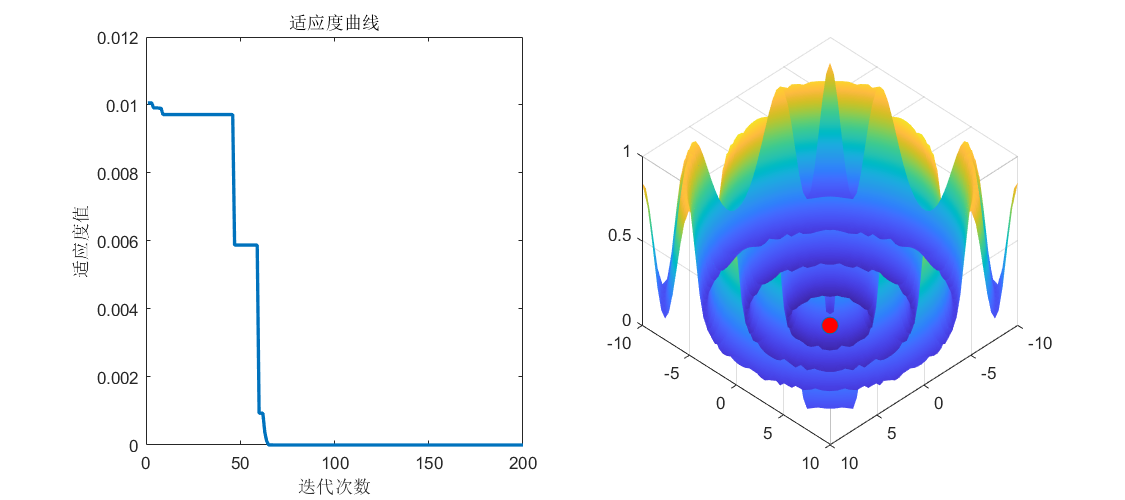

subplot(1, 2, 1)
plot(Convergence_curve, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度曲线');
len = 50;
xRange = linspace(lb(1), ub(1), len);
yRange = linspace(lb(2), ub(2), len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = ObjFun([xMap(i, j), yMap(i, j)]);
    end
end
subplot(1, 2, 2)
surf(xRange, yRange, zMap);
view(-45, -45);
shading interp
hold on
plot3(Alpha_pos(1), Alpha_pos(2), ObjFun(Alpha_pos), 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
set(gcf, 'Position', [400, 200, 900, 400]);

function result = ObjFun(x)
x1 = x(1);
x2 = x(2);
t = x1^2 + x2^2;
result = 0.5 + (sin(sqrt(t))^2 - 0.5) / (1 + 0.001 * t)^2;
end